# ***Environmental Torques Calculation***

This code calculates the maximum value for each one of the enviromental distrubances that the CubeSat is going to be subjected to.

# `List of Contents`

# **CubeSat Dimensions**

## Notice:

The code corresponds to a 3 unit CubeSat.

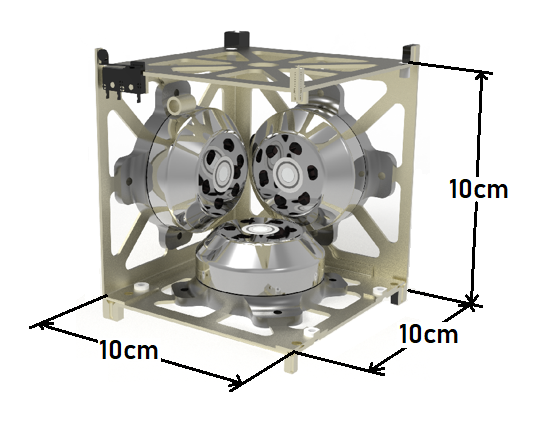

#### Length [$m$]

length = 0.3; 
disp(length)

    0.3000



#### Width [$m$]

width = 0.1; 
disp(width)

    0.1000



#### Area [$m^2$]

area = length*width; 
disp(area)

    0.0300



# **Solar Radiation Torque**

#### This section considers the force exerted by the incident radiation from the Sun on the surface of the CubeSat, that ultimately produces

#### a torque that affects the desired attitude.

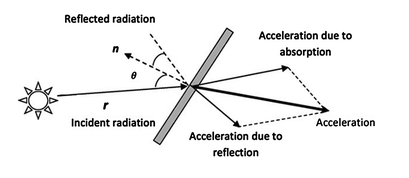

## Radiation Fractions $\left(\rho_a +\rho_s +\rho_d =1\right)$

### Absorbed Incident Radiation $\left(\rho_a \right)$

 p_a = 0.2584; 
 disp(p_a)

    0.2584



### Absorbed Reflected Specular Radiation $\left(\rho_s \right)$

 p_s = 0.7416; 
 disp(p_s)

    0.7416



### Absorbed Incident Diffuse Radiation $\left(\rho_d \right)$

p_d = 0;  
disp(p_d)

     0



## Solar Constant $\left(W\right)$  $\left\lbrack \frac{W}{m^2 }\right\rbrack$

The magnitude is valid only for ranges rom 500 km to 600000 km

W = 1358;
disp(W)

        1358



## Superficial exerted pressure by the effect of the Sun $\left\lbrack Nm^2 \right\rbrack$

P = 4.530*10^(-6);
disp(P)

   4.5300e-06



## Force Exerted from the absorbed incident radiation $\left\lbrack N\right\rbrack$

F_srp_a = p_a*P*area;
disp(F_srp_a)

   3.5117e-08



## Force Exerted from the reflected incident radiation (Specular) $\left\lbrack N\right\rbrack$

F_srp_s = 2*p_s*P*area;
disp(F_srp_s)

   2.0157e-07



## Force Exerted from the reflected incident radiation (Diffuse) $\left\lbrack N\right\rbrack$

### $\hat{s} \;$Direction

F_srp_d_s = p_d*P*area; 
disp(F_srp_d_s)

     0



### $\hat{n} \;$Direction       

F_srp_d_n = (2/3)*p_d*P*area; 
disp(F_srp_d_n)

     0



## Total exerted force $\left\lbrack N\right\rbrack$

### $\hat{s} \;$Direction Effect

 F_srp_total_s =  F_srp_a + F_srp_d_s; 
 disp(F_srp_total_s)

   3.5117e-08



### $\hat{n} \;$Direction Effect

 F_srp_total_n = F_srp_s + F_srp_d_n; 
 disp(F_srp_total_n)

   2.0157e-07



### Resultant Force

 F_srp_total = -[F_srp_total_s + F_srp_total_n, 0, 0];
 disp(norm(F_srp_total))

   2.3668e-07



## Solar Radiation Disturbance Torque $\left\lbrack \textrm{Nm}\right\rbrack$

### Position vector from the center of mass of the CubeSat to the center of solar pressure $\left\lbrack m\right\rbrack$

 rcm = [0.05, 0.05, 0.15]'; 
 disp(rcm)

    0.0500
    0.0500
    0.1500



### Obtained Torque

 M_sr = cross(rcm, F_srp_total);    
 
 M_srnorm = norm(M_sr); 
 
 disp(M_srnorm)

   3.7423e-08



# **Atmospheric Drag Torque**

**This section considers the torque produced by the collision of particles in the atmosphere against the body of the satellite.**

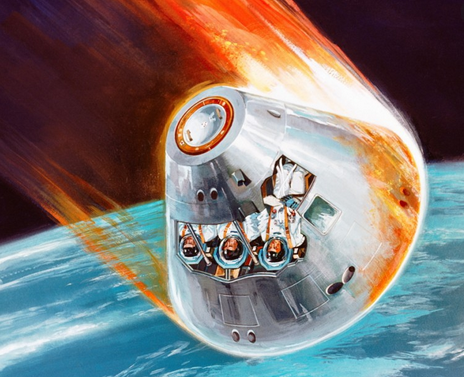 

## **CubeSat's Orbit Altitude **$\left\lbrack m\right\rbrack$

#### Minimum Design Orbit Range Altitude (The minimun value gives us the maximum output, therefore the wanted value for design)

h_sat = 400000;

## Atmospheric Drag Coefficient $\left(C_D \right)$ $\left\lbrack \textrm{Dimensionless}\right\rbrack$

 C_D = 2.5; 
 disp(C_D)

    2.5000



## CubeSat's Translational Velocity $\left\lbrack \frac{m}{s}\right\rbrack$

 V_sat = sqrt(((6.67430*10^(-11))*(5.9724*10^(24)))/(6378.137*1000 + h_sat));
 disp(V_sat)

   7.6687e+03



## Atmospheric Density $\left(\rho_{\textrm{atm}} \right)$$\left\lbrack \frac{\textrm{kg}}{m^3 }\right\rbrack$

  p_atm = 2.803*10^(-12); % This needs to be fixed, the value of density is not correlated to the orbits altitude slider
  disp(p_atm)

   2.8030e-12



## Atmospheric Drag Force  $\left\lbrack N\right\rbrack$

F_ad = -(1/2)*(C_D)*p_atm*((V_sat)^2)*area;

F_ad_total = [F_ad, 0, 0]';

disp(F_ad)

  -6.1816e-06



## Atmospheric Drag Disturbance Torque $\left\lbrack \textrm{Nm}\right\rbrack$

 M_ad = cross(rcm, F_ad_total); 
 
 M_adnorm = norm(M_ad);
 
 disp(M_adnorm)

   9.7739e-07



# **Gravitational Gradient Torque**

**This section considers the torque produced by the attraction of Earth's gravity.**

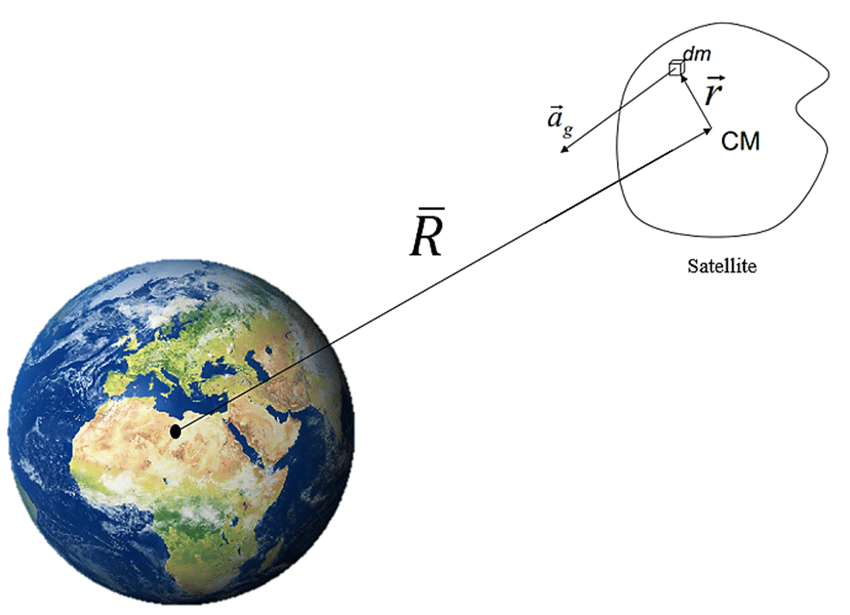

## Gravitational Constant $\left(G\right)$$\left\lbrack \frac{m^3 }{s^2 \textrm{kg}}\right\rbrack$

 G_grav = 6.6732*10^(-11);
 disp(G_grav)

   6.6732e-11



## Earth's Mass $\left\lbrack \textrm{kg}\right\rbrack$

M_earth = 5.92*10^(24); 
disp(M_earth)

   5.9200e+24



## Earth's Radius $\left\lbrack m\right\rbrack$

r_earth = 6378.137*1000; 
disp(r_earth)

     6378137



## CubeSat's Altitude respect the center of the Earth $\left\lbrack m\right\rbrack$

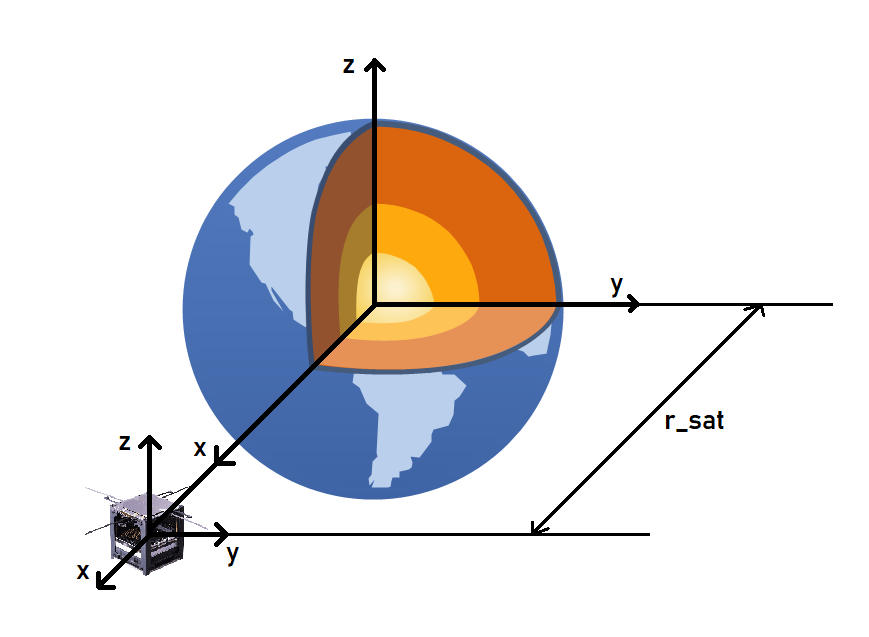

r_sat = h_sat + r_earth;
disp(r_sat)

     6778137



## Position vector from the COM of Earth to the COM of the CubeSat

p_BE = [ r_sat, 0, 0]';   
disp(p_BE)

     6778137
           0
           0



## Position vector from the COM of the CubeSat to the mass differential of the body

#### Using the farthest point to obtain the maximum value of torque.

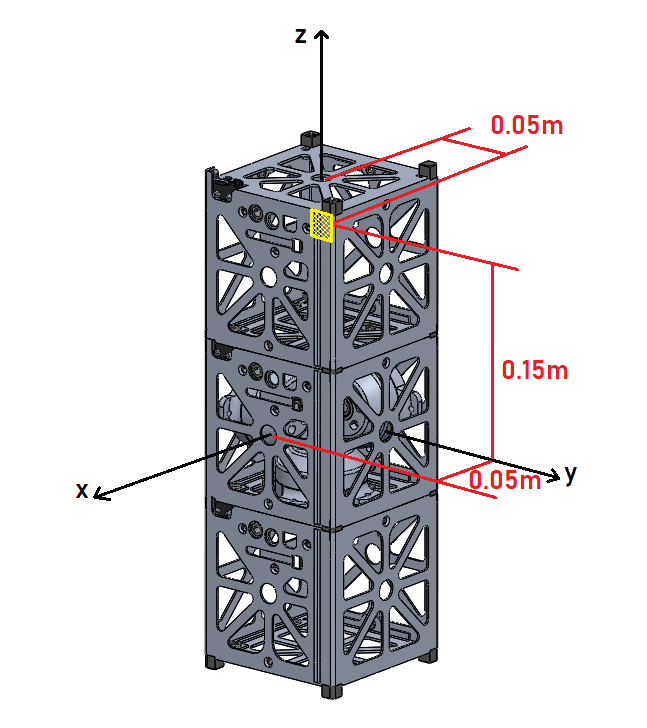

r_BE = [0.05, 0.05, 0.15]'; 
disp(r_BE)

    0.0500
    0.0500
    0.1500



## CubeSat's Inertia Tensor $\left\lbrack \textrm{kg}m^2 \right\rbrack$

Tensor = [3.4797*10^(-2) 1.4050*10^(-4) -2.3304*10^(-4); 1.4050*10^(-4) 3.5127*10^(-2) 5.5340*10^(-5); -2.3304*10^(-4) 5.5340*10^(-5) 8.7667*10^(-3)];   
disp(Tensor)

    0.0348    0.0001   -0.0002
    0.0001    0.0351    0.0001
   -0.0002    0.0001    0.0088



## Gravitational Gradient Disturbance Torque $\left\lbrack \textrm{Nm}\right\rbrack$

M_GG = cross((((3*G_grav*M_earth)/((norm(p_BE))^(5)))*p_BE), (Tensor*p_BE));  

M_GG_TOTAL = norm(M_GG);  

disp(M_GG_TOTAL)

   1.0356e-09



# **Magnetic Field Torque**

#### The magnetic field of the Earth causes a cyclic torque across the  spacecraft no matter its orientation due to interactions with the  spacecraft’s magnetic dipole.

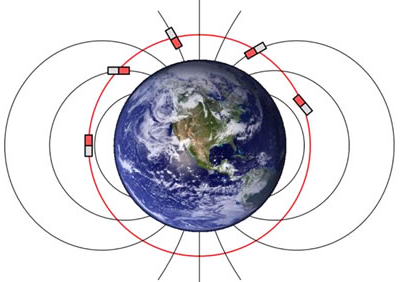

## Permeability Constant $\left(\mu_0 \right)$$\left\lbrack \frac{\textrm{Tm}}{A}\right\rbrack$

miu_o = 4*pi*10^(-7); 
disp(miu_o)

   1.2566e-06



## Earth's Magnetic Dipole Moment $\left(m_e \right)$ $\left\lbrack Am^2 \right\rbrack$

dipole = 7.71*10^(22);
disp(dipole)

   7.7100e+22



## Earth's Magnetic Dipole $\left(\mu_D =\frac{\mu_0 m_e }{4\pi }\right)$ 

miu_D = miu_o*dipole/4*pi;
disp(miu_D)

   7.6095e+16



## CubeSat's Magnetic Moment$\;\left\lbrack Am^2 \right\rbrack$

magnesat = [ 0.03, 0, 0]; %This values should give us a norm of around 0.03 Am^2
disp(norm(magnesat))

    0.0300



## Magnetic Latitude 

lambda =  0;

## Earth's Magnetic Field $\left\lbrack T\right\rbrack$

B_md = ((miu_D)/(norm(p_BE)^(3)))*[ (2*sind(lambda)), (cosd(lambda)), 0];
disp(B_md)

   1.0e-03 *

         0    0.2444         0



## Magnetic Field Disturbance Torque $\left\lbrack \textrm{Nm}\right\rbrack$

M_magnetic = cross(magnesat, B_md);

M_magneticresultant = norm(M_magnetic);

disp(M_magneticresultant)

   7.3307e-06



# **Combined Magnitude**

Mag_Total = M_adnorm +  M_srnorm + M_GG_TOTAL + M_magneticresultant;


## Solar Radiation Disturbance Torque $\left\lbrack \textrm{Nm}\right\rbrack$

disp(M_srnorm);

   3.7423e-08



## Atmospheric Drag Disturbance Torque $\left\lbrack \textrm{Nm}\right\rbrack$

disp(M_adnorm);

   9.7739e-07



## Gravitational Gradient Disturbance Torque $\left\lbrack \textrm{Nm}\right\rbrack$

disp(M_GG_TOTAL);

   1.0356e-09



## Magnetic Field Disturbance Torque $\left\lbrack \textrm{Nm}\right\rbrack$

disp(M_magneticresultant);

   7.3307e-06



## Combined Magnitude $\left\lbrack \textrm{Nm}\right\rbrack$

disp(Mag_Total);

   8.3465e-06

